path = uigetdir;

images = path + "\images";
masks = path + "\masks";

imdsTrain = imageDatastore(images,"ReadFcn",...
            @(x)imresize(rgb2gray(imread(x)),[256,256]));numClasses = 2;
classes = ["zp","bg"];
labels = [1 0];
pxdsTrain = pixelLabelDatastore(masks,classes,labels,"ReadFcn",@(x)im2bw(imresize(imread(x),[256 256])));

tbl = countEachLabel(pxdsTrain);
numberPixels = sum(tbl.PixelCount);

frequency = tbl.PixelCount/numberPixels;
classWeights = 1 ./ frequency;

numFiles = numel(imdsTrain.Files); % Total files in train datastore=205
indices = randperm(numFiles); % random indices for each file 
validationRatio = 0.2; % 20% of the dataset will be valData
numVal = round(validationRatio * numFiles); % exact number of files that are valData =41
valIndices = indices(1:numVal); %  41 indices from indices matrix will be given to valIndices 1x41
trainIndices = indices(numVal+1:end); % 205-41=164 indices from indices matrix will be given to trainIndices 1x164



imdsTrainSplit = subset(imdsTrain,trainIndices);
imdsValSplit = subset(imdsTrain,valIndices);
pxdsTrainSplit = subset(pxdsTrain,trainIndices);
pxdsValSplit = subset(pxdsTrain,valIndices);

dsTrain = combine(imdsTrainSplit,pxdsTrainSplit);
dsVal = combine(imdsValSplit,pxdsValSplit);


netlayers=[ 
    imageInputLayer([256 256 1]);
%--1d
    convolution2dLayer(3, 32, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer();
    maxPooling2dLayer(2, 'Stride', 2);
%--2d
    convolution2dLayer(3, 128, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer('Name', 'relu2conv');
    maxPooling2dLayer(2, 'Stride', 2);
%--3d
    convolution2dLayer(3, 128, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer('Name', 'relu3conv');%<==== concatenate to 3u
    maxPooling2dLayer(2, 'Stride', 2);
%--4d
    convolution2dLayer(3, 512, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer();
    maxPooling2dLayer(2, 'Stride', 2);
%------- Expanding path
%--4u
    transposedConv2dLayer([2 2], 512, 'Stride', 2);
    batchNormalizationLayer; 
    reluLayer();
    
%--3u
    transposedConv2dLayer([2 2], 128, 'Stride', 2);   
    concatenationLayer(3, 2, 'Name', 'concat3');%<========
%    convolution2dLayer(3, 128, 'Padding', 'same');
    batchNormalizationLayer;
    reluLayer();
%--2u
    transposedConv2dLayer([2 2], 128, 'Stride', 2);
    concatenationLayer(3, 2, 'Name', 'concat2');%<========
    
    batchNormalizationLayer;
    reluLayer();
%--1u
    transposedConv2dLayer([2 2], 32, 'Stride', 2);
    batchNormalizationLayer;
    reluLayer();

    convolution2dLayer(1, numClasses);

    softmaxLayer();
    pixelClassificationLayer('Classes', classes, 'ClassWeights', classWeights);
];

% Create layer graph
lgraph = layerGraph(netlayers);

% Connect relu3up to the second input of concat
lgraph = connectLayers(lgraph, 'relu3conv', 'concat3/in2');
% Connect relu3up to the second input of concat
lgraph = connectLayers(lgraph, 'relu2conv', 'concat2/in2');
% Analyze the network
analyzeNetwork(lgraph);

netlayers=lgraph;

options = trainingOptions('adam',...
    'InitialLearnRate',0.001,...
    'MaxEpochs',30,...
    'MiniBatchSize',25,...
    'Plots','training-progress',...
    'ValidationData',dsVal);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:37 |       38.74% |       41.75% |       0.8342 |       0.6507 |          0.0010 |
|       9 |          50 |       00:22:58 |       97.17% |       97.04% |       0.0843 |       0.0814 |          0.0010 |
|      12 |          70 |       00:42:06 |       98.08% |              |       0.0615 |              |          0.0010 |
|=========================================================================================

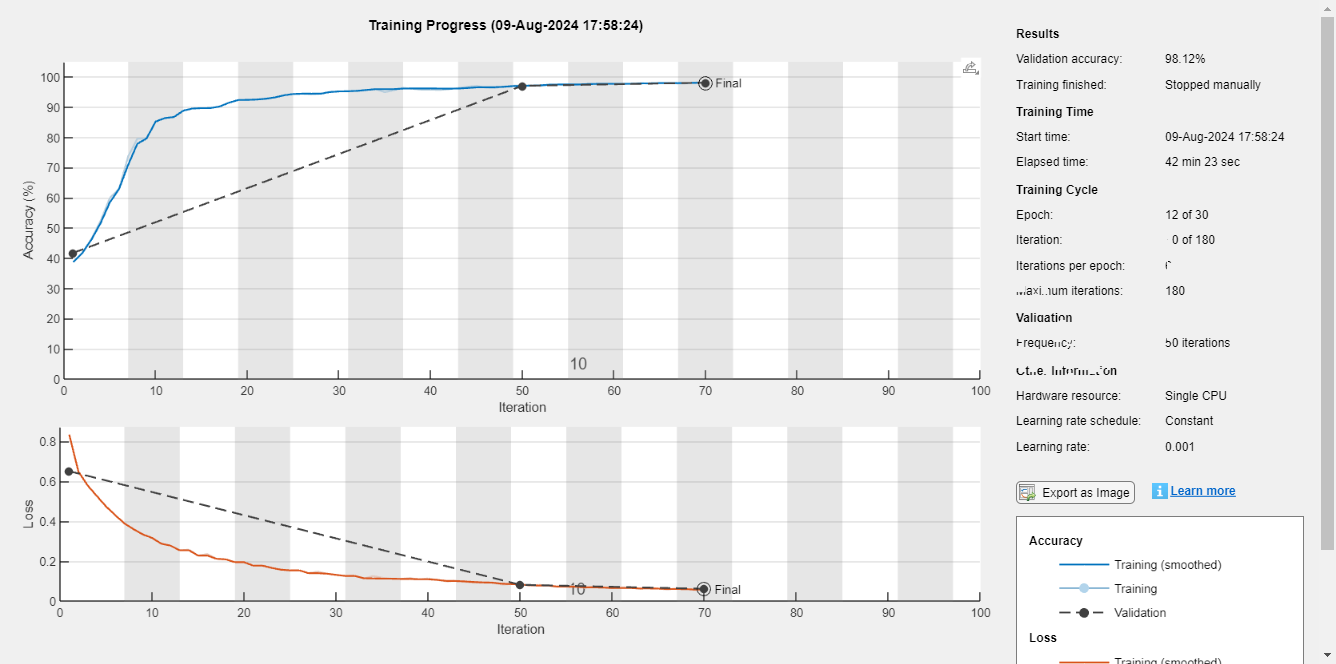

netlayers = trainNetwork(dsTrain,netlayers,options);

save('zpne.mat','netlayers');

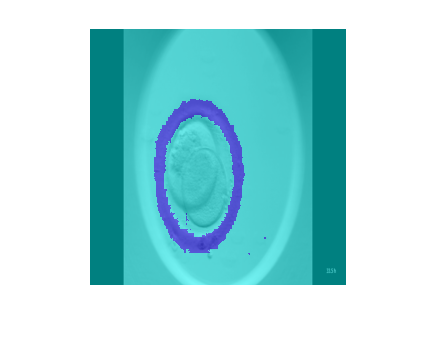

I = readimage(imdsTrainSplit,2);
C = semanticseg(I,netlayers,Classes=classes);
B = labeloverlay(I,C);
imshow(B)